clc;
clear;
close all;

## Esercizio 1.

range = [10, 20];
n = randi(range, 1);

A = zeros(n);
for i = 1 : n
    
    v = zeros(n, 1);
    for j = 1 : n
        v(j) = j;
    end

    A(i, :) = v;
end
A

norme = [norm(A, 1), norm(A), norm(A, inf)];

% arr = [det(A), eigs(A), norm(A, 1), norm(A), norm(A, 2)];
% t = array2table(arr, 'VariableNames', {"Determinante", ""})
fprintf("Determinante: %d\n", det(A));

t = table(eigs(A), 'VariableNames', "Autovalori");
t2 = table(norme, 'VariableNames', "Norme");
disp(t);
disp(t2);

clc;
clear;
close all;

## Esercizio 2.

Creo la matrice 10x10

n = 10;
A = -n + 20 * rand(10);
while det(A) < 10e-5
    A = -n + 20 * rand(10);
end

x = ones(n, 1);
b = A \ x;

[U, b2] = gauss_p(A, b);
x1 = U \ b2;

err = norm(x - x1) / norm(x);
fprintf("Errore relativo: %d", err);

clc;
clear;
close all;

## Esercizio 3.

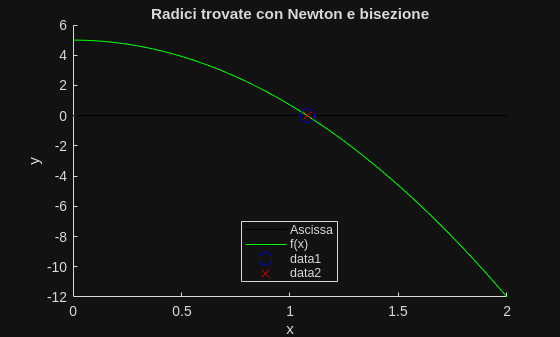

f = @(x) cos(pi .* x ./ 4) - 4 .* x .* x + 4;
f1 = @(x) -pi .* 4 .* sin(pi .* x ./ 4) - 8 .* x;

[xb, kb] = bisezione(f, 1, 2, 10e-5, 100);
[xn, kn] = newton(f, f1, 1, 10e-5, 100);

x = linspace(0, 2, 100);
figure;
hold on;

title("Radici trovate con Newton e bisezione");
xlabel("x");
ylabel("y");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "Ob", "MarkerSize", 10);
plot(xb, f(xb), "Xr", "MarkerSize", 8);

legend("Location", "best");


hold off;

function [U, b2] = gauss_p(A, b)

    % gauss_p: funzione che calcola la riduzione di Gauss con pivoting e 
    % prende in ingresso la matrice A e il vettore di termini noti b.
    % [U, b2] = gauss_p(A, b) restituisce la riduzione di Gauss, non i 
    % termini noti

    % Controlli preliminari sulle dimensioni di matrice, vettore e sul
    % determinante di A
    [m, n] = size(A);
    if m ~= n
        error("la matrice deve essere quadrata");
    end
    if size(b, 1) ~= n || size(b, 2) ~= 1
        error("b deve essere un vettore colonna con n righe");
    end
    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end


    for k = 1 : n-1

        [~, pos] = max(abs(A(k:n,k))); % Prendo le righe da k in giù nella colonna corrente
        % In pratica scarto il valore e prendo solo la posizione

        % Però ho il valore nel vettore che sto considerando, non della
        % matrice originale:
        l = pos + k - 1;

        % E poi scambio le righe:
        % Prendo la riga k E la riga l
        A([k l], :) = A([l k], :);
        b([k l]) = b([l k]);


        for i = k+1 : n
            m = A(i, k) / A(k, k);

            % Calcolo della nuova riga per ottenere una triangolare
            % inferiore
            A(i, :) = A(i, :) - m * A(k, :);

            b(i) = b(i) - m * b(k);
        end
    end

    % Assegno il valore corretto alle matrici da restituire
    U = A;
    b2 = b;
end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    
    % bisezione: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xb, kb] = bisezione(f, a, b, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo la variabile fa con f(a) per non doverla calcolare più
    % volte
    fa = f(a);

    % Controllo che nell'intervallo sia contenuta la radice che cerco
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [%g, %g]", a, b);
    end


    % Inizio algoritmo iterativo da k a kmax
    for kb = 1 : kmax
       
        % Formula bisezione
        xb = (a + b) / 2;
        
        % Aggiorno l'immagine della x trovata per non doverla calcolare più
        % volte
        fxb = f(xb);

        % Controllo la positività dell'immagine trovata e aggiorno
        % l'intervallo
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end
        
        % Condizioni di arresto
        if abs(fxb) < tau
            return;
        end

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xn, kn] = newton(f, fder, x0, tau, kmax)

    % newton: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [xn, kn] = newton(f, fder, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo xn
    xn = x0;

    % Se il punto passato è già soluzione lo restituisco
    if(abs(f(x0)) < tau)
        kn = 0;
        return;
    end

    % Inizio algoritmo iterativo da k a kmax
    for kn = 1 : kmax
        
        f1 = fder(x0);

        if(abs(f1) < tau)
            error("La derivata tende a 0: cambia il valore x0");
        end

        % Formula Newton
        xn = x0 - f(x0) / f1;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(f(xn)) < tau || abs(xn - x0) < tau * abs(x0)
            return;
        end

        % Aggiornamento variabili
        x0 = xn;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end